lenaImg = imread("Lena.gif");
doubleLenaImg = im2double(lenaImg)

doubleLenaImg =     0.5373    0.5333    0.5216    0.5333    0.5412    0.5255    0.5255    0.5176    0.5176    0.5412    0.5059    0.5137    0.5176    0.4980    0.5059    0.5059    0.5098    0.5137    0.5412    0.5412    0.5569    0.5725    0.5922    0.5922    0.5843    0.5804    0.5608    0.5255    0.4667    0.4627    0.3529    0.3137    0.2510    0.2431    0.2392    0.2706    0.2784    0.2863    0.2863    0.2902    0.3059    0.2902    0.2980    0.3098    0.2980    0.2941    0.3059    0.2980    0.3059    0.3059
    0.5373    0.5333    0.5216    0.5333    0.5412    0.5255    0.5255    0.5176    0.5176    0.5412    0.5059    0.5137    0.5176    0.4980    0.5059    0.5059    0.5098    0.5137    0.5412    0.5412    0.5569    0.5725    0.5922    0.5922    0.5843    0.5804    0.5608    0.5255    0.4667    0.4627    0.3529    0.3137    0.2510    0.2431    0.2392    0.2706    0.2784    0.2863    0.2863    0.2902    0.3059    0.2902    0.2980    0.3098    0.2980    0.2941    0.3059    0.2980   

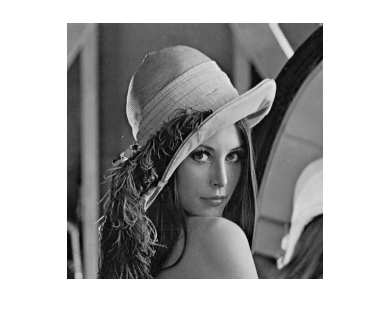

imshow(doubleLenaImg)

LPF = ones(5,5)/25

LPF =     0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400


filteredLenaImg = imfilter(doubleLenaImg, LPF, 'replicate')

filteredLenaImg =     0.5335    0.5322    0.5325    0.5297    0.5280    0.5267    0.5238    0.5235    0.5197    0.5173    0.5175    0.5139    0.5073    0.5076    0.5075    0.5064    0.5145    0.5217    0.5318    0.5443    0.5603    0.5707    0.5793    0.5840    0.5816    0.5682    0.5432    0.5178    0.4720    0.4223    0.3678    0.3230    0.2792    0.2626    0.2557    0.2620    0.2707    0.2811    0.2882    0.2907    0.2932    0.2974    0.2985    0.2963    0.2991    0.2991    0.2985    0.3002    0.2998    0.2969
    0.5311    0.5296    0.5299    0.5275    0.5253    0.5230    0.5205    0.5192    0.5155    0.5131    0.5139    0.5107    0.5048    0.5054    0.5064    0.5053    0.5125    0.5209    0.5311    0.5434    0.5595    0.5707    0.5791    0.5832    0.5807    0.5671    0.5424    0.5144    0.4689    0.4188    0.3642    0.3181    0.2764    0.2582    0.2505    0.2560    0.2660    0.2772    0.2844    0.2877    0.2905    0.2935    0.2932    0.2918    0.2946    0.2951    0.2943    0.2963 

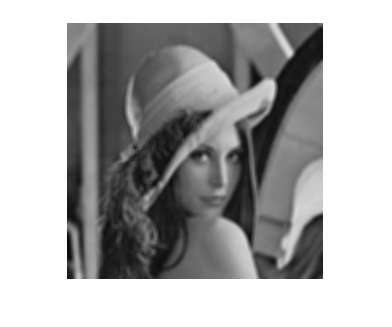

imshow(filteredLenaImg)

lenaPsnr = psnr(doubleLenaImg, filteredLenaImg, 1)

lenaPsnr = 25.7335